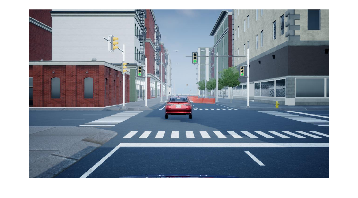

%Load Image
img  = imread('frame108.jpg');
imshow(img)

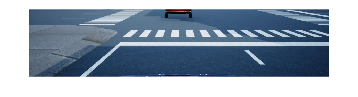

grayImg = rgb2gray(img);

% Get the size of the original image
[height, width, ~] = size(img);

% Define the ROI for the left half up to the center
roi_x = 1 :width;
roi_y = (3*height/5):height;

% Crop the image to the defined ROI
croppedImg = img(roi_y, roi_x, :);

% Display the cropped image
imshow(croppedImg);

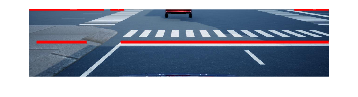


% Load the image
img = croppedImg;

% Convert the image to grayscale (if not already)
grayImg = rgb2gray(img);

% Apply edge detection to the grayscale image
edgeImg = edge(grayImg, 'canny');

% Perform the Hough Transform
[H, theta, rho] = hough(edgeImg);

% Find peaks in the Hough Transform
numPeaks = 10;  % You can adjust the number of peaks to detect
peaks = houghpeaks(H, numPeaks);

% Extract lines based on the peaks
lines = houghlines(edgeImg, theta, rho, peaks);

% Display the original cropped image
imshow(img);
hold on;

% Plot the detected lines on the image
for i = 1:length(lines)
    xy = [lines(i).point1; lines(i).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'red');
end

hold off;


% Load the image and perform line detection as previously described

% Define the angle range for the specific line you want to detect
angleRange = [-90, -80]; % Adjust this range as needed

% Define the minimum and maximum line length (in pixels)
minLineLength = 350; % Adjust as needed
maxLineLength = 980; % Adjust as needed


% Initialize an empty array to store the specific lines
specificLines = [];

% Iterate through the detected lines and filter based on angle and length
for i = 1:length(lines)
    angle = lines(i).theta; % Get the angle of the line
    lineLength = norm(lines(i).point1 - lines(i).point2) % Calculate line length
    
    % Check if the angle falls within the specified range and line length is within the specified range
    if angle >= angleRange(1) && angle <= angleRange(2) && ...
       lineLength >= minLineLength && lineLength <= maxLineLength;
        specificLines = [specificLines, lines(i)];
    end
end

lineLength = 215

lineLength = 888

lineLength = 318

lineLength = 58

lineLength = 147

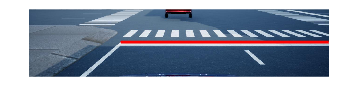


% Display the original cropped image
imshow(img);
hold on;

% Plot the detected specific lines on the image
for i = 1:length(specificLines)
    xy = [specificLines(i).point1; specificLines(i).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'red');
end

hold off;


% Check if specific lines were detected
if ~isempty(specificLines)
    % Specific lines were detected
    disp('Specific line detected in the image.');
else
    % No specific lines were detected
    disp('No specific line detected in the image.');
end

Specific line detected in the image.


% if ~isempty(specificLinesAtBottom)
%     distanceToTrafficLight = 0;
%     disp('bottom')
% end
% 
% if ~isempty(specificLineAtTop)
%     distanceToTrafficLight = 5; 
%     disp('top')
% end


Calculating the distance from the stop line

% Assuming you want to calculate the distance for a specific line (e.g., the first line in specificLines)
% Make sure that specificLines is not empty

% Extract the specific line you are interested in
specificLine = specificLines(1); % Change the index if needed

% Extract endpoints of the specific line
x1 = specificLine.point1(1);
y1 = specificLine.point1(2);
x2 = specificLine.point2(1);
y2 = specificLine.point2(2);

% Calculate PixelLineLength
PixelLineLength = sqrt((x2 - x1)^2 + (y2 - y1)^2)

PixelLineLength = 888


% Given parameters
VehicleHeight = 1.246 + 0.271;
FocalLength = 1190; %same for x and y
SensorHeight = 360;
width = 4

width = 4


% Calculate the distance (D)
D = (VehicleHeight * FocalLength) / (PixelLineLength * SensorHeight);


D = FocalLength*width / PixelLineLength

D = 5.3604

% Display the distance
fprintf('Distance to the line: %.2f meters\n', D);

Distance to the line: 5.36 meters


## Creating images from video

% videoFile = 'Origin.avi';
% vidObj = VideoReader(videoFile);
% 
% outputFolder = 'output_images';
% if ~exist(outputFolder, 'dir')
%     mkdir(outputFolder);
% end
% 
% %Loop through the frames
% frameNumber = 1;
% while hasFrame(vidObj)
%     % Read the current frame
%     frame = readFrame(vidObj);
% 
%     % Define the output file name (e.g., frame001.jpg, frame002.jpg, etc.)
%     outputFileName = sprintf('frame%03d.jpg', frameNumber);
% 
%     % Specify the full path to save the image
%     outputPath = fullfile(outputFolder, outputFileName);
% 
%     % Save the frame as an image
%     imwrite(frame, outputPath);
% 
%     % Increment the frame number
%     frameNumber = frameNumber + 1;
% end
% 
% delete(vidObj);